# Machine Learning Online Class

## =============== Part 1: Loading movie ratings dataset ================

fprintf('Loading movie ratings dataset.\n\n');

Loading movie ratings dataset.



%  Load data
load ('ex8_movies.mat');

%  Y is a 1682x943 matrix, containing ratings (1-5) of 1682 movies on 
%  943 users
%
%  R is a 1682x943 matrix, where R(i,j) = 1 if and only if user j gave a
%  rating to movie i

%  From the matrix, we can compute statistics like average rating.
fprintf('Average rating for movie 1 (Toy Story): %f / 5\n\n', ...
        mean(Y(1, R(1, :))));

Average rating for movie 1 (Toy Story): 3.878319 / 5



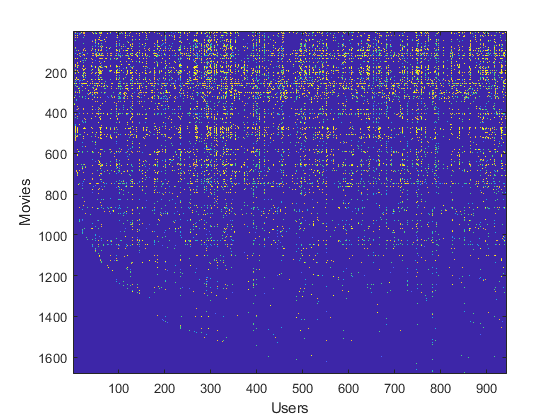

%  We can "visualize" the ratings matrix by plotting it with imagesc
imagesc(Y);
ylabel('Movies');
xlabel('Users');

## ============ Part 2: Collaborative Filtering Cost Function ===========

%  Load pre-trained weights (X, Theta, num_users, num_movies, num_features)
load ('ex8_movieParams.mat');

%  Reduce the data set size so that this runs faster
num_users = 4; 
num_movies = 5; 
num_features = 3;
% X是电影的特征矩阵，一行一个样本特征向量
% Theta是用户的参数矩阵，一行一个用户参数向量
X = X(1 : num_movies, 1 : num_features);
Theta = Theta(1:num_users, 1:num_features);
Y = Y(1 : num_movies, 1 : num_users);
R = R(1 : num_movies, 1 : num_users);

%  Evaluate cost function
J = cofiCostFunc([X(:) ; Theta(:)], Y, R, num_users, num_movies, num_features, 0);
           
fprintf(['Cost at loaded parameters: %f '...
         '\n(this value should be about 22.22)\n'], J);

Cost at loaded parameters: 22.224604 
(this value should be about 22.22)


## ============== Part 3: Collaborative Filtering Gradient ==============

fprintf('\nChecking Gradients (without regularization) ... \n');


Checking Gradients (without regularization) ... 


%  Check gradients by running checkNNGradients
checkCostFunction;

    2.4734    2.4734
   -3.3642   -3.3642
    3.0220    3.0220
   -0.0045   -0.0045
    1.3398    1.3398
   -3.0521   -3.0521
    2.0962    2.0962
    0.0222    0.0222
   -5.1495   -5.1495
    2.6312    2.6312
   -1.3667   -1.3667
    0.3324    0.3324
    1.4416    1.4416
   -0.5971   -0.5971
   -1.8176   -1.8176
    5.4534    5.4534
   -4.0567   -4.0567
   -0.4537   -0.4537
   -0.2140   -0.2140
    0.5173    0.5173
    3.0944    3.0944
    1.1219    1.1219
    0.7806    0.7806
   -0.2328   -0.2328
   -1.3480   -1.3480
    0.7513    0.7513
   -2.6773   -2.6773
The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your cost function implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 7.05038e-13


## ========= Part 4: Collaborative Filtering Cost Regularization ========

%  Evaluate cost function
J = cofiCostFunc([X(:) ; Theta(:)], Y, R, num_users, num_movies, ...
               num_features, 1.5);
           
fprintf(['Cost at loaded parameters (lambda = 1.5): %f '...
         '\n(this value should be about 31.34)\n'], J);

Cost at loaded parameters (lambda = 1.5): 31.344056 
(this value should be about 31.34)


## ======= Part 5: Collaborative Filtering Gradient Regularization ======

fprintf('\nChecking Gradients (with regularization) ... \n');


Checking Gradients (with regularization) ... 


%  Check gradients by running checkNNGradients
checkCostFunction(1.5);

   -0.5757   -0.5757
    1.7256    1.7256
    1.8087    1.8087
    5.5917    5.5917
    0.1996    0.1996
   -7.6902   -7.6902
   -4.3051   -4.3051
  -10.4999  -10.4999
   -0.0717   -0.0717
   -3.6842   -3.6842
    0.5828    0.5828
   -2.0054   -2.0054
   -1.7368   -1.7368
   -1.9312   -1.9312
   -1.4579   -1.4579
   -2.4870   -2.4870
    2.1670    2.1670
    3.8779    3.8779
    1.6977    1.6977
    7.5505    7.5505
   14.9200   14.9200
   -1.5953   -1.5953
   -0.7142   -0.7142
    2.0173    2.0173
    1.9999    1.9999
    7.5847    7.5847
    0.2629    0.2629
The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your cost function implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 2.01165e-12


## ============== Part 6: Entering ratings for a new user ===============

movieList = loadMovieList();

%  Initialize my ratings
my_ratings = zeros(1682, 1);

% Check the file movie_idx.txt for id of each movie in our dataset
% For example, Toy Story (1995) has ID 1, so to rate it "4", you can set
my_ratings(1) = 4;

% Or suppose did not enjoy Silence of the Lambs (1991), you can set
my_ratings(98) = 2;

% We have selected a few movies we liked / did not like and the ratings we
% gave are as follows:
my_ratings(7) = 3;
my_ratings(12)= 5;
my_ratings(54) = 4;
my_ratings(64)= 5;
my_ratings(66)= 3;
my_ratings(69) = 5;
my_ratings(183) = 4;
my_ratings(226) = 5;
my_ratings(355)= 5;

fprintf('\n\nNew user ratings:\n');



New user ratings:


for i = 1 : length(my_ratings)
    if my_ratings(i) > 0 
        fprintf('Rated %d for %s\n', my_ratings(i), ...
                 movieList{i});
    end
end

Rated 4 for Toy Story (1995)
Rated 3 for Twelve Monkeys (1995)
Rated 5 for Usual Suspects, The (1995)
Rated 4 for Outbreak (1995)
Rated 5 for Shawshank Redemption, The (1994)
Rated 3 for While You Were Sleeping (1995)
Rated 5 for Forrest Gump (1994)
Rated 2 for Silence of the Lambs, The (1991)
Rated 4 for Alien (1979)
Rated 5 for Die Hard 2 (1990)
Rated 5 for Sphere (1998)


## ================== Part 7: Learning Movie Ratings ====================

fprintf('\nTraining collaborative filtering...\n');


Training collaborative filtering...


%  Load data
load('ex8_movies.mat');

%  Y is a 1682x943 matrix, containing ratings (1-5) of 1682 movies by 
%  943 users
%
%  R is a 1682x943 matrix, where R(i,j) = 1 if and only if user j gave a
%  rating to movie i

%  Add our own ratings to the data matrix
% 相当于新增了一个个用户的数据
Y = [my_ratings, Y];
R = [(my_ratings ~= 0), R];
%  Normalize Ratings
[Ynorm, Ymean] = normalizeRatings(Y, R);

%  Useful Values
num_users = size(Y, 2);
num_movies = size(Y, 1);
num_features = 10;

% Set Initial Parameters (Theta, X)
% 正态分布的随机数
X = randn(num_movies, num_features);
Theta = randn(num_users, num_features);

initial_parameters = [X(:); Theta(:)];

% Set options for fmincg
options = optimset('GradObj', 'on', 'MaxIter', 100);

% Set Regularization
lambda = 10;
% 开始训练X Theta
theta = fmincg (@(t)(cofiCostFunc(t, Ynorm, R, num_users, num_movies, ...
                                num_features, lambda)), ...
                initial_parameters, options);

Iteration     1 | Cost: 7.493336e+05
Iteration     2 | Cost: 4.880861e+05
Iteration     3 | Cost: 2.987959e+05
Iteration     4 | Cost: 2.322157e+05
Iteration     5 | Cost: 1.770114e+05
Iteration     6 | Cost: 1.465684e+05
Iteration     7 | Cost: 1.268106e+05
Iteration     8 | Cost: 1.162170e+05
Iteration     9 | Cost: 1.080068e+05
Iteration    10 | Cost: 1.027622e+05
Iteration    11 | Cost: 9.724652e+04
Iteration    12 | Cost: 9.367597e+04
Iteration    13 | Cost: 9.234529e+04
Iteration    14 | Cost: 8.890725e+04
Iteration    15 | Cost: 8.677051e+04
Iteration    16 | Cost: 8.556865e+04
Iteration    17 | Cost: 8.443566e+04
Iteration    18 | Cost: 8.131790e+04
Iteration    19 | Cost: 7.945750e+04
Iteration    20 | Cost: 7.858425e+04
Iteration    21 | Cost: 7.774777e+04
Iteration    22 | Cost: 7.665230e+04
Iteration    23 | Cost: 7.550082e+04
Iteration    24 | Cost: 7.492713e+04
Iteration    25 | Cost: 7.432257e+04
Iteration    26 | Cost: 7.351994e+04
Iteration    27 | Cost: 7.301211e+04
I

% Unfold the returned theta back into U and W
% 将X和Theta恢复正常形式
X = reshape(theta(1 : num_movies * num_features), num_movies, num_features);
Theta = reshape(theta(num_movies * num_features + 1 : end), num_users, num_features);

fprintf('Recommender system learning completed.\n');

Recommender system learning completed.



Program paused. Press enter to continue.


## ================== Part 8: Recommendation for you ====================

% 新用户的预测也是先用整体求出后，加上均值
p = X * Theta';
% 对训练出来的预估结果加上均值

p =     1.8800    1.9710    2.0311    1.7991    2.5449    2.0332    1.5129    2.0184    2.2048    2.3918    2.3236    2.2005    2.3358    1.6370    2.0754    1.6219    3.0511    1.5942    1.9533    1.6246    1.5455    1.8629    1.9774    1.5970    2.2110    2.3486    1.8730    1.5669    2.0410    2.0554    2.2106    1.7546    1.5966    1.9052    1.6522    1.8215    2.3256    2.0306    2.7489    2.0571    1.4315    1.7024    2.8677    2.3950    2.2417    2.3529    1.8727    1.7900    2.2600    0.3619
    2.1265    2.8987    2.3836    1.7005    2.7510    2.5709    2.0496    2.9104    2.5260    2.6200    2.9841    2.6371    2.9629    3.1121    2.9302    2.0108    3.1642    1.4477    2.5561    2.0562    2.1126    2.2198    2.7754    2.6062    2.9052    2.9431    1.9467    2.0210    2.6974    2.2473    2.5499    2.4426    1.8797    2.1294    2.3299    1.7422    2.7357    2.7374    3.0183    2.0295    1.8609    2.2883    3.1284    2.9603    2.7075    2.7283    2.5027    1.9355    2.4170    1

my_predictions = p(:, 1) + Ymean;

movieList = loadMovieList();

[r, ix] = sort(my_predictions, 'descend');
fprintf('\nTop recommendations for you:\n');


Top recommendations for you:


for i = 1 : 10
    j = ix(i);
    fprintf('Predicting rating %.1f for movie %s\n', my_predictions(j), movieList{j});
end

Predicting rating 4.5 for movie Star Wars (1977)
Predicting rating 4.3 for movie Titanic (1997)
Predicting rating 4.2 for movie Raiders of the Lost Ark (1981)
Predicting rating 4.1 for movie Return of the Jedi (1983)
Predicting rating 4.0 for movie Empire Strikes Back, The (1980)
Predicting rating 4.0 for movie Braveheart (1995)
Predicting rating 3.9 for movie Shawshank Redemption, The (1994)
Predicting rating 3.9 for movie Godfather, The (1972)
Predicting rating 3.8 for movie Schindler's List (1993)
Predicting rating 3.8 for movie Fugitive, The (1993)


fprintf('\n\nOriginal ratings provided:\n');



Original ratings provided:


for i = 1 : length(my_ratings)
    if my_ratings(i) > 0 
        fprintf('Rated %d for %s\n', my_ratings(i), movieList{i});
    end
end

Rated 4 for Toy Story (1995)
Rated 3 for Twelve Monkeys (1995)
Rated 5 for Usual Suspects, The (1995)
Rated 4 for Outbreak (1995)
Rated 5 for Shawshank Redemption, The (1994)
Rated 3 for While You Were Sleeping (1995)
Rated 5 for Forrest Gump (1994)
Rated 2 for Silence of the Lambs, The (1991)
Rated 4 for Alien (1979)
Rated 5 for Die Hard 2 (1990)
Rated 5 for Sphere (1998)
